# **Image Processing**

An image is a 2D array containing MxN elements called *picture elements *or pixels for short. Much like any 2D array or a matrix, an image contains M rows and N columns, where each element is denoted by a pair of indices (i,j). Standard matrix operations like scaling, rotation, reflection apply to an image. An image (**A**) can be transformed by applying a set of operations through matrix multiplcations, each transform matrix (**T**) having a particular operation, i.e. rotation by 90 degrees. Try this simple example below

%% This is just an example code.
% Comment this section out in the final version.
A = [2 0]'; % vector A stretching between the 
% origin (0,0) and point (2,0) 
theta = 90;
T = [cosd(theta) -sind(theta); sind(theta) cosd(theta)]

T =      0    -1
     1     0


A_rot_90 = T * A; % apply transform T (rot by 90 deg) to A

One of major objectives of linear algebra is to create, design and apply such linear transforms to matrices; images are a subset of matrices. Since matrix operations form a part of linear algebra that falls beyond the scope of this coursework, we will focus on transforms that can be easily done through elementwise multiplcation, i.e. using the `.* `operation. 

If you have ever got hold of a simple image processsing tool -- Photoshop, filters in camera app, social media apps, etc, you might have at least once used the blur or the sharpen tool. The idea is simple - pick a blur tool of a preset radius, hold and drag across the image to blur out (or sharpen) certain regions in the image.

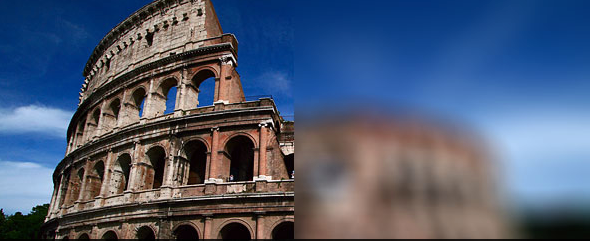 

While a common use of blurring or sharpening an image might produce cosmetic effects on the image, they often important use in signal processsing, image processing, computer vision, robotics. Blurring suppresses small-scale details to bring out dominant features in the signal (image), while sharpening can detect edges to identify, classify and label specific features. 

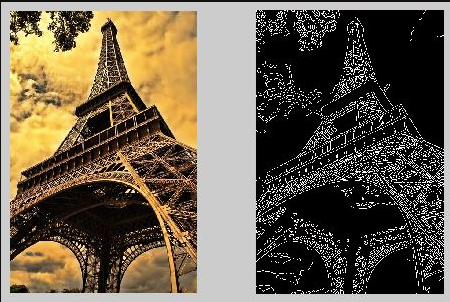

The concept of holding such a tool to "rub" across the image to get the desired effect has a rather boring name - **convolution**. Whether it is the latest face detection software on your iPhone 12, the now-archaic Snapchat dog-ears filter, amping up the bass at a concert, designing noise-cancellation headphones, predicting stock prices, or Tesla's latest Autopilot feature, at the heart of every such feature lies the basic operation of convolution. The "tool" that you "hold" in your hand also has an equally boring name - **kernel**. The basic idea is to design a filter kernel and apply the convolution operation to a signal (or an image) to get the desired effect - accentuate dominant features, smudge out strong local features, find image outline, etc. 

In the final project, you will apply the basic operation of convolution to an image to a) detect a tumor, b) determine the outline of a human brain. One involves blurring, while the other uses edge-detection. You are provided with the kernel fo both the operations. All that is needed is to "walk" through every point (using nested for-loops) and apply the kernel through elementwise multiplcation on each point, or pixel. 

## **Blur tool**

An MRI scan of a human brain (315 x 561 pixels) is provided in the csv format. Load `brain.csv` and save it to the variable `image`. Save the number of rows to variable `M` and number of cols to the variable `N, `using the size function. Do NOT hand type the values (you will lose a point here). You code must be able to find the size of the image automatically. The `size()` function has two outputs rows and cols in a 2x1 array. Save the first element of the output to M and the second to N.

% Read csv file
% image = ?;
% [M, N] = ?;

Create a duplicate of your image to another variable `blur`. Plot `image `and `blur `using the `subplot` function (2 rows, 1 col). Use `imshow()`  to plot images.

% blur = ?;
% figure()
% subplot 
% imshow(?);
% subplot 
% ??

At this point both images should appear identical. We will now apply the blur tool on the image and detect the point with the highest intensity along the way. The blur kernel (I) here is a simple 3x3 unit matrix (use: `ones()`)  of radius r = 3.   

% Build blur tool kernel
% r = ?;
% I = ?;


Create two nested loops with indices i and j running along the rows and cols. Within the loop, apply kernel (I) to each point of the `image` matrix using elementwise multiplication on array subset surrounding the given point, and having the same size as the kernel to perform successful multiplication. At the same time determine whether current value is the maximum value (max); save the indices (i,j) to Y and X. Before you proceed with setting up the nested FOR-loops try and answer a few questions:

- If **I** is a 3x3 array, then what is the size of the array subset to perform elementwise multiplication?

- Applying the kernel is similar to taking moving average on each point, only this time the average is taken in two dimensions. How can you take the average of all the points in a 2D array?

- The mean-product of kernel with the array subset is stored to the corresponding location of the `blur `matrix. Would the elements of `blur` bordering the edges be different or the same as the ones in `image?` 

- Why would i for the max value get assigned to Y and j to X?

First work out the indices, loops on a 5x5 test matrix on paper. Take r = 1. 

% initialize X, Y and max to zero

% Run FOR-loops over the image
for i = 
    for j =
        
            % Compare the current value of image(i,j) with max. Set to max if true.     
            ?
            
        end
    end
end

% Print location of the tumor. Will you use %d, %s or %f to print the
% indices?
fprintf("Located tumor at (,) \n", ??);

% plot image and blur - 2x1 subplot using imshow() function
figure()

Invalid use of operator.

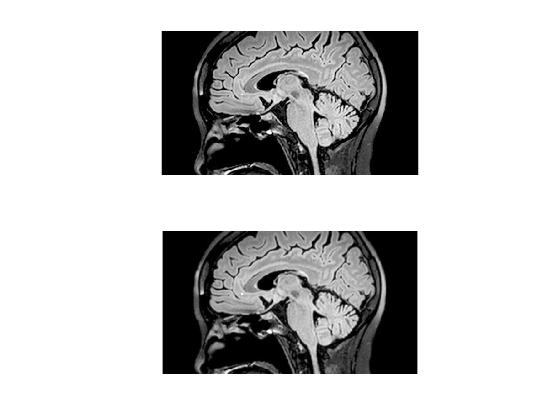

% ignore the message above

## Edge detection tool

Next we apply an edge detection tool (T) to the blurred image to markoff different regions. Performing elementwise multiplication with the given kernel will allow us to determine the outline. We will first copy `blur `to `edge, `and set radius to 1. 

    

% Build kernel for edge detection

edge = blur;
T = ?;
r = ?;


Run two nested FOR-loops to apply kernel T to the blurred image. Applying edge detection requires summing up the product of the subsection of blur and T. Q: How will you sum all the elements of a 2D array? Also note that the matrices being multipled must be of same size, meaning the range specified using the colon operator should be such that T and the array subset getting multiplied with T should be of same size. So first perform elementwise multiplication between blur and T, followed by taking their sum. Assign the result to the corresponding on the  `edge` matrix.

for i = 
    for j = 
        ? % You need to fill out only one line here to perform the operations described above
    end
end


## Thresholding

There is one last step, where we increase image contrast by setting values above a certain "threshold" to zero. Since the image is on a greyscale, the colors that you see are intensities of grey from 0(black) to 1(white). This presents us with a perfect opportunity to apply logical filter such that our final image has only 0s and 1s, thereby presenting us with a high-contrast image.

- What is the logical condition if all points in the image below 0.2 is to be set to 1 (white)? 

- Can the result of mask be saved back to the `edge` matrix? See previous example on applying a mask to an array and saving the result back to itself. This step shouldn't require a FOR-loop or the IF-block.

% % apply threshold
edge = ?;


## Final image

In the final step plot the original scan (image) on top, the final thresholded scan (edge) and overlay the point (X,Y) with a red circle to mark off the location of the tumor. 

% plot image and edge
figure()
subplot ?
imshow(image);
subplot 212
imshow(edge);
% plot a red circle [X,Y] on top of the second image. use plot() function.
?
